# Notas de clase: Modelación experimental

## Clase 1: Presentación del curso

Mapa mental con las ideas de la clase.

## Tema: Objeto y método de la modelación experimental

### Clase 2: Objeto y método de la modelación experimental

### Clase 3: Objeto y método de la modelación experimental

### Clase 4: Objeto y método de la modelación experimental

## Tema: Métodos no paramétricos de identificación

### Clase 5: Métodos no paramétricos de la respuesta temporal

#### Respuesta temporal para sistemas de primer orden

Una función de transferencia para un sistema de primer orden tiene la forma $G\left(s\right)=\frac{{ae}^{-\tau \mathrm{s}} }{s+b}=\frac{{ke}^{-\tau \mathrm{s}} }{Ts+1}$, siendo $k=\frac{a}{b},T=\frac{1}{b}$. Dicha función de transferencia corresponde entonces con la ecuación diferencial 


$$T\overset{\ldotp }{y} +y=ku\left(t-\tau \right)$$


cuya solución viene dada por


$$y=Ak\left(1-e^{-\frac{t-\tau }{T}} \right)u_s \left(t-\tau \right),{\;\;\;u}_s \left(t-\tau \right)=\left\lbrace \begin{array}{ll}
1 & t\ge \tau \\
0 & \mathrm{en}\;\mathrm{otro}\;\mathrm{caso}
\end{array}\right.$$


para el caso de una entrada escalón con amplitud $A$, $u_A \left(t-\tau \right)=\left\lbrace \begin{array}{ll}
A & t\ge \tau \\
0 & \mathrm{en}\;\mathrm{otro}\;\mathrm{caso}
\end{array}\right.$. 

En dicho contexto, es posible dar a los parámetros de la función de transferencia una interpretación acorde con la forma de la solución de la ecuación diferencial:

- $T-$ constante de tiempo del sistema: se deduce haciendo $t-\tau =T$, en cuyo caso $y\simeq 0\ldotp 632Ak$. De forma tal, $T$ es el tiempo que tarda el sistema en ir de su valor inicial al $63\ldotp 2%$ de su valor final (de estabilización).

- $k-$ ganancia del sistema: se deduce calculando el $\lim_{t\longrightarrow \infty } y\left(t\right)=Ak$. De forma tal, $k$ determina la amplificación con la que el sistema responde a la entrada.

- $\tau -$ retardo puro del sistema

- $A-$ amplitud de la entrada escalón aplicada al sistema

**Ejemplo: comparación de sistemas de primer orden**

¿Qué podría decirse de los siguientes sistemas de primer orden?


$$G_1 \left(s\right)=\frac{0\ldotp 5}{s+0\ldotp 25}=\frac{2}{4s+1},\;G_2 \left(s\right)=\frac{2}{s+4}=\frac{0\ldotp 5}{0\ldotp 25s+1}$$


Comparando en MatLab: con la función [tf](https://www.mathworks.com/help/control/ref/tf.html) podemos crear funciones de transferencia especificando los coeficientes del polinimio del numerador y del denominador.

clear;clc;close all
tf1=tf([0.5],[1 0.25])

tf1 =
 
    0.5
  --------
  s + 0.25
 
Continuous-time transfer function.



tf2=tf(2,[1 4])

tf2 =
 
    2
  -----
  s + 4
 
Continuous-time transfer function.



Con la función [step](https://www.mathworks.com/help/control/ref/lti.step.html) podemos graficar rápidamente la respuesta del sistema a una entrada de tipo escalón unitario.

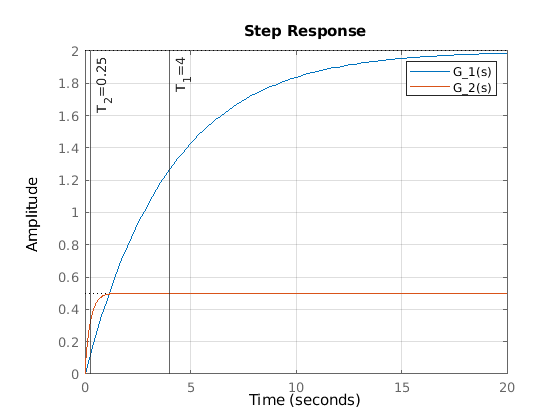

figure(1)
clf
step(tf1,20)
hold on
step(tf2,20)
grid on
xline([4,0.25],'-',{'T_1=4','T_2=0.25'})
legend({'G_1(s)','G_2(s)'})

En conclusión, el primer sistema crece más lento pero se estabiliza en un mayor valor mientras que el segundo crece más rápido y se estabiliza en un menor valor.

#### Ajuste mediante modelos de primer orden

**Método visual: **Los valores de los 3 parámetros se deducen de la gráfica

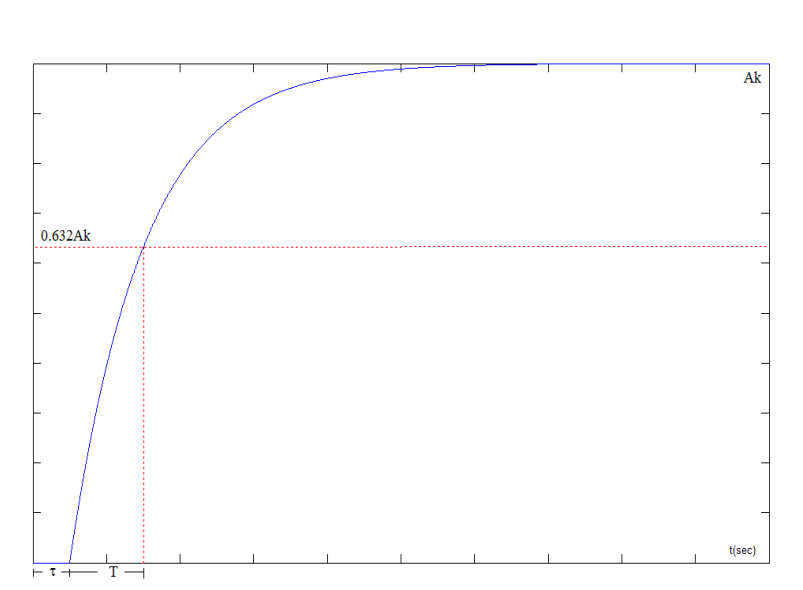

**Método de regresión lineal: **Los valores de los 3 parámetros se deducen mediante regresión. Se parte de la estructura $y=Ak\left(1-e^{-\frac{t-\tau }{T}} \right)$ y se deduce que $\ln \left(1-\frac{y}{Ak}\right)=-\frac{t}{T}+\frac{\tau }{T}$, o visto de otra forma, el problema se ha llevado a la forma $y=at+b,T=-\frac{1}{a},\tau =-\frac{b}{a}$. El valor de $k$ se calcula fácilmente como $k=\frac{\Delta y}{\Delta u}=\frac{y_0 -y_{\mathrm{ss}} }{u_0 -u_A }$.

**Ejemplo:**

Se genera un modelo de segundo orden especificando los ceros, polos, ganancia y retardo del sistema mediante la función [zpk](https://www.mathworks.com/help/control/ref/zpk.html). El sistema que elegimos para el ejemplo no tiene ceros, tiene dos polos (-1.8 y -2.2), tiene una ganancia de 1.24 y un retardo de 0.89 segundos.

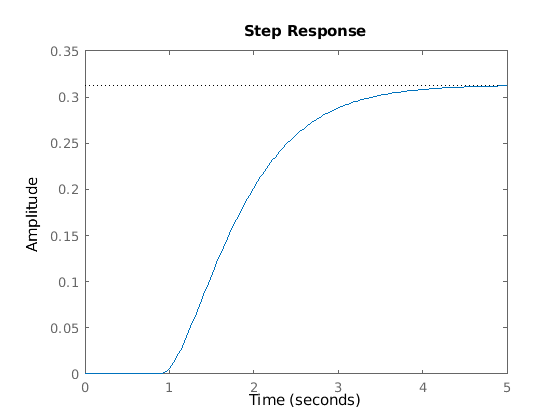

%creación de un modelo de segundo orden
G=zpk([],[-1.8 -2.2],1.24,'InputDelay',0.89);
%generación de la respuesta temporal
figure(1)
clf
step(G);%comprobamos que el sistema se estabiliza

%[y,t]=step(G);%recolectamos los datos tal y como los arroja matlab
[y,t]=step(G,[0:0.01:6]);%recolectamos los datos a nuestro gusto
inicio=find(y>0,1)%identificamos el dato a partir del cual el modelo responde a la entrada

inicio = 91

yvals=y(inicio:end);%valores útiles de y
tvals=t(inicio:end);%valores útiles de t
k=yvals(end)-y(1);%valor de k según la fórmula

**Método de regresión**

[p,s]=polyfit(tvals,log(1-yvals/(k+eps)),1);%regresión lineal al logaritmo de y
T=-1/p(1);tau=-p(2)/p(1);%valores de parámetros  T y tau según las fórmulas
tf_est=tf(k,[T 1],'InputDelay',tau)%función de transferencia resultante

tf_est =
 
                    0.313
  exp(-1.44*s) * ------------
                 0.5551 s + 1
 
Continuous-time transfer function.



**Método gráfico**

tau2=t(inicio);%primer valor donde y reacciona a la entrada
valT=find(y>0.632*y(end),1);%posición donde y alcanza el 63.2% de su valor final
T2=t(valT)-tau2;%valor de T por definición
tf_est2=tf(k,[T2 1],'InputDelay',tau2)%función de transferencia resultante

tf_est2 =
 
                  0.313
  exp(-0.9*s) * ----------
                1.08 s + 1
 
Continuous-time transfer function.



**Comparación entre métodos**

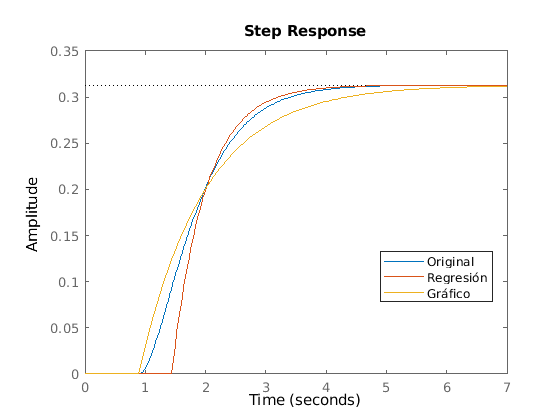

figure(1)
hold on
step(tf_est)
step(tf_est2)
legend({'Original','Regresión','Gráfico'},'Location','best')

#### Respuesta temporal para sistemas de segundo orden

Los sistemas de segundo orden son de la forma $G\left(s\right)=\frac{{ae}^{-\tau \mathrm{s}} }{s^2 +bs+c}=\frac{k\omega_0^2 e^{-\tau s} }{s^2 +2\zeta \omega_0 s+\omega_0^2 },\omega_0^2 =c,k=\frac{a}{c},\zeta =\frac{b}{2\sqrt{c}}$. Dicha función de transferencia se corresponde con la ecuación diferencial 


$$\overset{\ldotp \ldotp }{y} +2\zeta \omega_0 \overset{\ldotp }{y} +\omega_0 y=k\omega_0 u\left(t-\tau \right)$$


El caso que nos interesa en esta ecuación ocurre cuando $\zeta <1,{u\left(t-\tau \right)=u}_A \left(t-\tau \right)$. ya que las raíces del polinomio característico serán imaginarias y la solución de la ecuación diferencial vendría dada por

$y=Ak\left\lbrack 1-\frac{1}{\sqrt{1-\zeta^2 }}e^{-\zeta \omega_0 \left(t-\tau \right)} \mathrm{sen}\left(\omega_1 \left(t-\tau \right)+\phi \right)\right\rbrack u_s \left(t-\tau \right),\omega_1 =\omega_0 \sqrt{1-\zeta^2 },\phi =\arccos \zeta$.

De forma similar al caso de la respuesta temporal en sistemas de primer orden, es posible dar interpretación a los parámetros del modelo de orden 2 como sigue

- $k-$ ganancia del sistema

- $\tau -$ retardo puro del sistema

- $\omega_0 -$ frecuencia natural (no amortiguada) del sistema

- $\omega_1 -$ frecuencia amortiguada del sistema

- $\zeta -$ razón de amortiguamiento

- $A-$ amplitud de la entrada escalón del sistema

Dependiendo de los valores de $\zeta$ tendremos 4 casos:

- $\zeta =0$, **sistema no amortiguado**

- $0<\zeta <1$, **sistema subamortiguado**

- $\zeta =1$, **sistema críticamente amortiguado**

- $\zeta >1$, **sistema sobreamortiguado**

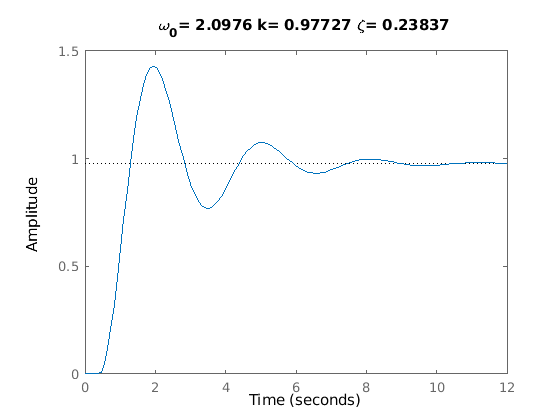

a=4.3;
b=1;
c=4.4;
tau=0.4;
tf1=tf(a,[1 b c],'InputDelay',tau);%función de transferencia a partir de los datos
figure(1)
clf
step(tf1);
title(["\omega_0= "+sqrt(c)+" k= "+a/c+" \zeta= "+b/(2*sqrt(c))])%cálculo de valores de los parámetros

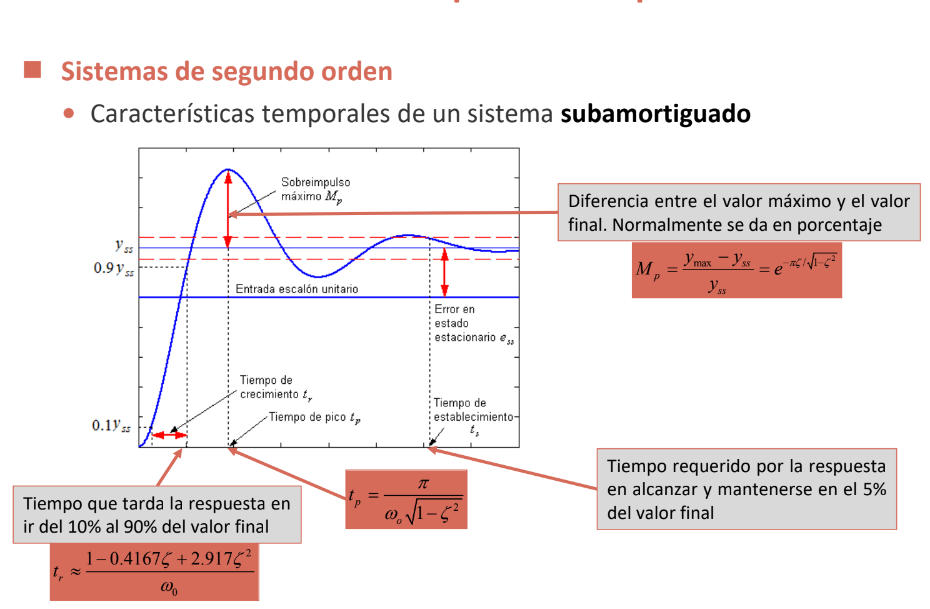

#### Ajuste mediante modelos de segundo orden

Para ajustar el modelo de segundo orden utilizamos un **método gráfico**. Para tal fin, determinamos 4 valores: el retardo del modelo $\tau$, el valor final del modelo $\Delta y$, el sobreimpulso máximo $M_p =e^{-\pi \frac{\zeta }{\sqrt{1-\zeta^2 }}} \Longrightarrow \zeta =\frac{1}{\sqrt{1+\frac{\pi^2 }{\ln^2 \left(\frac{M_p }{\Delta y}\right)}}}$ y el tiempo de pico $t_p =\frac{\pi }{\omega_0 \sqrt{1-\zeta^2 }}\Longrightarrow \omega_0 =\frac{\pi }{t_p \sqrt{1-\zeta^2 }}$

[y,t]=step(tf1);%recolección de datos por recomendación de MatLab
inicio=find(y>0,1);%dato a partir del cual el sistema reacciona
tau=t(inicio)%tiempo a partir del cual el sistema reacciona

tau = 0.4605

deltaY=y(end)-y(1)%delta de y por definición

deltaY = 0.9767

Mp=max(y)-y(end);%sobreimpulso máximo pode definición
Tp=t(y==max(y))-tau;%tiempo de pico, se le debe restar el retardo
%zeta=1/sqrt(1+(pi/log(Mp/deltaY))^2)%valor de z (diapositivas)
zeta=-log(Mp)/sqrt(pi^2+log(Mp)^2)%valor de z (Soderstrom)

zeta = 0.2447

omega0=pi/(Tp*sqrt(1-zeta^2))%valor de omega0 por fórmulas

omega0 = 2.1987

tf_est=tf(deltaY*omega0^2,[1 2*zeta*omega0 omega0^2],'InputDelay',tau)%función de transferencia estimada

tf_est =
 
                          4.722
  exp(-0.461*s) * ---------------------
                  s^2 + 1.076 s + 4.834
 
Continuous-time transfer function.



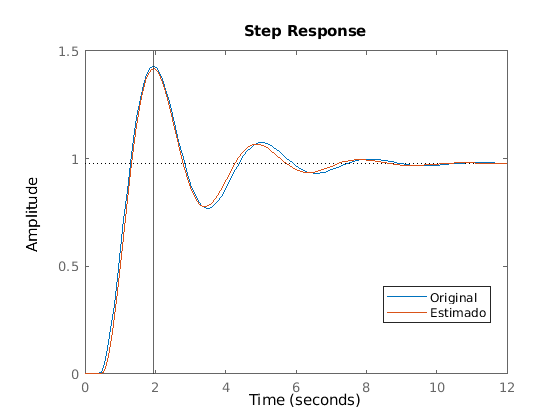

figure(2)
clf
step(tf1)
hold on
step(tf_est)
xline(Tp+tau)
legend({'Original','Estimado'},'Location','best')

#### Resumen de los métodos de respuesta temporal

- Se identifica si el sistema presenta oscilaciones o no. A los modelos que oscilan los aproximaremos por un sistema de orden 2, todos los demás modelos serán aproximados por un modelo de orden 1.

- Seleccionar el método para identificar parámetros: gráfico o de regresión.

- Implementar las fórmulas para identificar los valores de parámetros.

- Validar los resultados de la función de transferencia estimada versus la curva original.

### Clase 6: Método no paramétrico de la correlación

#### Estimación de la secuencia de ponderación mediante correlación


$$\hat{g} \left(\tau \right)=\frac{R_{\mathrm{yu}} \left(\tau \right)}{R_u \left(0\right)}\approx \frac{\frac{1}{N}\sum_{t=\tau }^{N-1} y\left(t\right)u\left(t-\tau \right)}{\frac{1}{N}\sum_{t=0}^{N-1} u^2 \left(t\right)},\tau =0,1,\ldotp \ldotp \ldotp ,N-1,\;\;\hat{g} \left(\tau \right)=0\;\mathrm{si}\;\tau \ge N$$


clear;clc;close all
N=500;%número de muestras
M=24;%Longitud secuencia de ponderación
noise=0.2;%amplitud del ruido
num=[1];%numerador de la tf
den=[1 0.5];%denominador de la tf
tf1=tf(num,den,1)%función de transferencia objetivo

tf1 =
 
     1
  -------
  z + 0.5
 
Sample time: 1 seconds
Discrete-time transfer function.



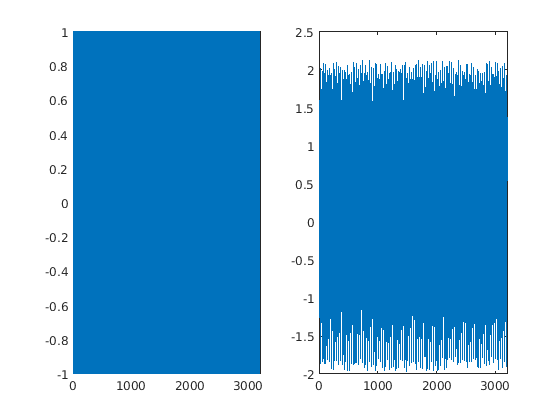

u=2*(prbs(5,N,[1 0 1 0 0])-0.5);%señal prbs de N datos con valores entre -1 y 1
xdata=0:1:N-1;%instantes de muestreo
[y,t]=lsim(tf1,u,xdata);%simulación del modelo con la entrada diseñada
y=y+noise*rand(length(y),1);%adición del ruido a la entrada
figure(1)
clf
subplot(1,2,1), plot(t,u)%gráfica de la entrada
subplot(1,2,2), plot(t,y)%fráfica de la salida

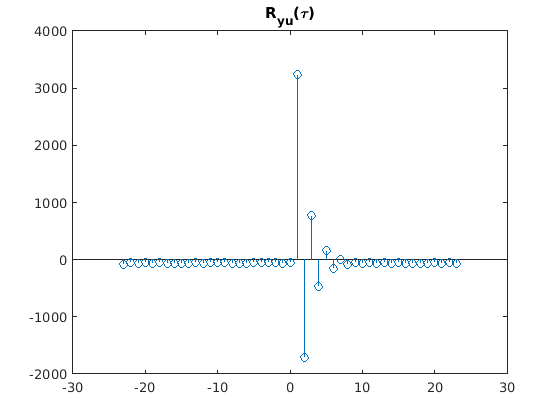

[cyu,lagsyu] = xcorr(y,u,M-1);%M elementos de la correlación entre y y u
[cu,lagsu] = xcorr(u,0);%correlación de la entrada con ella misma en el instante 0
tf_est=cyu(lagsyu>=0)/cu;%fórmula para la secuencia de ponderación
delay=length(den)-length(num);%cálculo del retardo del sistema
tf_real=ldiv([1],[1 0.5],M-delay);%cálculo de la secuencia de ponderación
tf_real=[zeros(1,delay) tf_real];%adición del retardo a la secuencia de ponderación
figure(2)
clf
stem(lagsyu,cyu)%gráfica de la correlación de y y u
title('R_{yu}(\tau)')

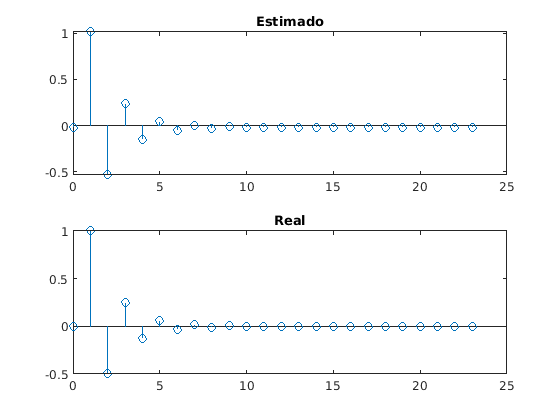

pdata=0:1:M-1;
figure(3)
clf
subplot(2,1,1)
stem(pdata,tf_est)%secuencia estimada
title('Estimado')
subplot(2,1,2)
stem(pdata,tf_real)%secuencia real
title('Real')

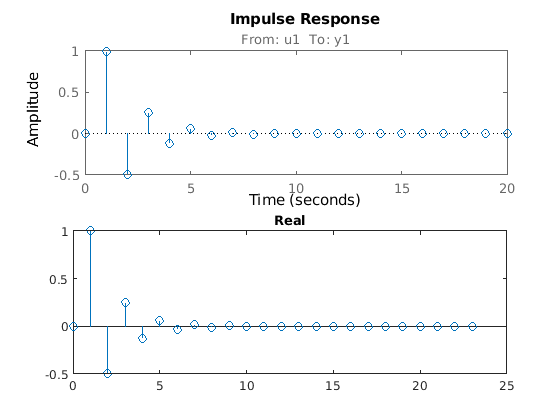

data = iddata(y,u');%datos para usar las funciones mejoradas de MatLab
sys = impulseest(data,M);%secuencia de ponderación estimada por MatLab
figure(4)
clf
subplot(2,1,1)
h = impulseplot(sys);%secuencia de ponderación estimada por MatLab
subplot(2,1,2)
stem(pdata,tf_real)%secuencia real
title('Real')

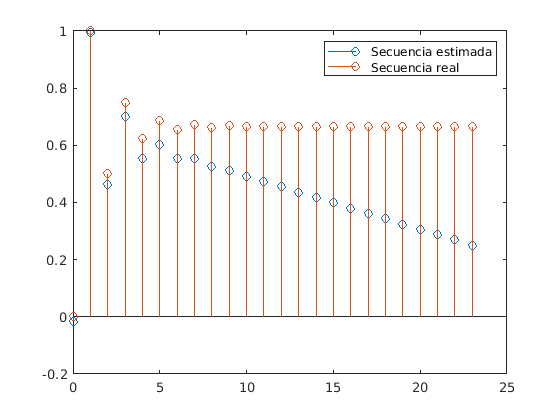

figure(5)
clf
response=cumsum(tf_est.*ones(length(tf_est),1));%convolución a la entrada de tipo escalón para la secuencia estimada
stem(pdata,response)
hold on
response2=cumsum(tf_real'.*ones(length(tf_est),1));%convolución a la entrada de tipo escalón para la secuencia real
stem(pdata,response2)
legend({'Secuencia estimada', 'Secuencia real'})

## Tema: Métodos paramétricos de identificación

### Clase 7: Método de mínimos cuadrados

### Clase 8: Método de mínimos cuadrados

### Clase 9: Métodos de variable instrumental

### Clase 10: Métodos de variable instrumental

# Funciones adicionales para el curso

function funresult=ldiv(a,b,N)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Function (ldiv) : calculate inverse Z-transform by long division 
% Author : Tamer mohamed samy abdelazim Mellik
% Contact information : 
%Department of Electrical & Computer Engineering,
%University of Calgary,
%2500 University Drive N.W. ,
%Calgary, AB T2N 1N4 ,
%Canada .
% email :abdelasi@enel.ucalgary.ca  
% email : tabdelaz@ucalgary.ca
% Webpage : http://www.enel.ucalgary.ca/~abdelasi/
% Date    : 2-5-2002
% Version : 1.0.0
%Example
% This function like deconv but it help if the numerator less or equal degree of denominator
% if you have this function (It must arranged in terms of minus power of Z):
%              1
% G(z)= -----------------      
%             -1     -2
%      ( 5 - Z  - 3 Z  )
% and you want to calculate long division or inverse Z transform :
% The numerator  is a=[1] and  the denominator is b= [5 -1 -3 ]
% call the function ldiv(a,b) to get the funresult 20 items (default)
% another example :
%                -2     -3 
%       ( 5 - 3 Z  + 4 Z  )
%  G(z)-----------------      
%              -1     -2
%        (5 - Z  - 3 Z )
% a=[5 0 -3 4] , b= [5 -1 -3 ] and you want the funresult 100 terms !
% ldiv(a,b,100) 
% Note : The author doesn't have any responsibility for any harm caused by the use of this file
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%a numerator
%b denominator
%default order of the filter == 20
funresult=[];
if nargin < 3
    if nargin > 1
            N=20;
    else
            disp('Usage: M = ldiv(a,b,N)')
            disp('a:numerator , b denominator and N is the order of the resultant filter')
            return
    end 
end
if size(a) < 1
    disp('Error: numerator must at least have one element not empty')
    return
end
if size(b) < 1
    disp('Error: denominator must at least have one element not empty')
    return
end
if b(1)==0
    disp('Error: The first element of denominator must have nonzero value')
    return
end
if size(b) < 2
    funresult=a./b;
    for i =length(funresult)+1:N
       funresult(i)=0;
    end
    return
end
for i = length(a)+1:N
    a(i)=0;
end
for i = 1 : N
    funresult(i)=a(1)/b(1);
    if length(a)>1
            for k= 2:length(b)
                if k > length(a)
                    a(k)=0;
                end
                a(k)=a(k)-funresult(length(funresult))*b(k);
            end
        for i = 1:length(a)-1
                a(i)=a(i+1);
        end
        a=a(1:length(a)-1);
    end
end
end